# Exercise 7.1 - Chirp signals

## Observations

Note that a chirp is a signal whose frequency changes over time. If it increases with time, then it is said to be an up-chirp. On the contrary, if it decreases, it is referred to as a down-chirp.

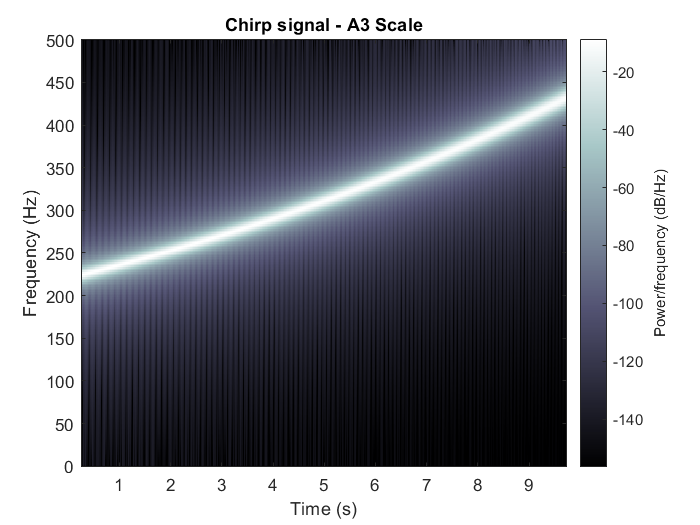

f0 = 220;               % A3 frequency.
f1 = 440;               % A4 frequency.
fs = 1000;              % Sampling frequency.
n = 0 : (10 * fs) - 1;  % Discrete time samples array.

% Generate the chirp signal.
y = chirp(n / fs, f0, 10, f1, 'logarithmic');
sound (y, fs);

% Draw its spectrogram.
spectrogram(y, hanning(512), 500, 512, fs, 'yaxis');
title('Chirp signal - A3 Scale'), colormap bone

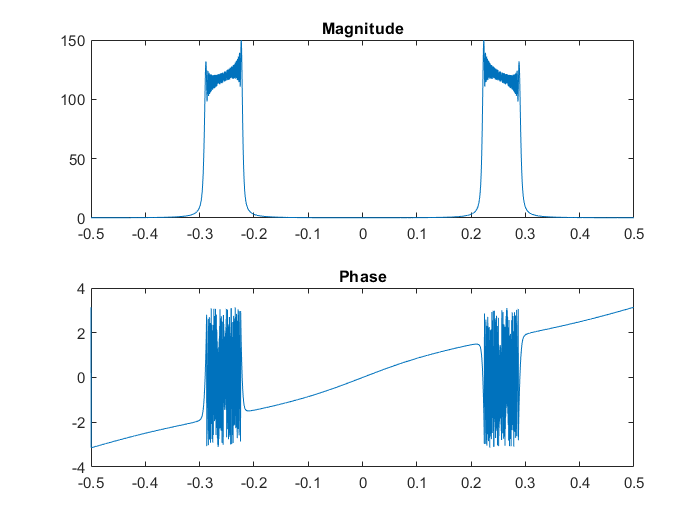


% Fourier Transform.
N = 4096;                                       % # of points.
spectrum = fft(y, N);                           % Compute FFT.
spectrumShifted = fftshift(spectrum);           % Shift to the origin.

% Plot the magnitude and phase of the FFT.
f = (0 : (N - 1)) / N - 0.5;    % OX-axis boundaries.
subplot(211), plot(f, abs(spectrumShifted)), title('Magnitude');
subplot(212), plot(f, angle(spectrumShifted)), title('Phase');